# Laboratorio 2 

## Robótica 2021 - 1 

### Luis Alberto Chavez Castro

### Jorge Luis Reina Jara

### Edwin Alexander Casallas Moreno

##  Modelo cinemático inverso *FANUC LR Mate 200 ib*

### **Parte I, Robot y Ruta.**

El robot asignado para el desarrolllo de este laboratorio fue el modelo* Fanuc LR Mate 200 ib*. Se asigna un modelo de robot industrial a cada equipo de trabajo y un plano en el que debe crear una ruta y simular el movimiento de seguimiento del robot. Deberá presentar al menos la simulación de esa ruta, pueden crear y simular otras rutas y/o otros planos..

### Localización de ruta.

Plano - Vector, significa que la ruta que el robot va a simular debe estar en un plano normal al vector indicado en la tabla.

La ruta debe tener una de las dos formas mostradas en la figura 2. Cada grupo selecciona la que deseen.

La dimensión L debe ser aproximadamente 0,4 del alcance horizontal máximo del robot.

El grupo decide la posición de la ruta en el espacio cartesiano de manera que quede dentro del espacio diestro del robot.

la ruta seleccionada por el equipo de trabajo es la que se muestra a continuación:

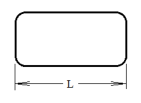

### Características y modelo del robot

Busque información técnica del robot, obtenga catálogos de fabricante, presente en el informe:

#### 1. Imagen del robot.

el Robot a modelar es el siguiente:

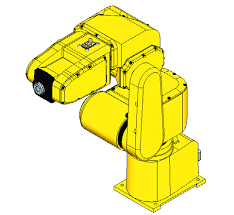

#### 2. Capacidad de carga.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iB posee una capacidad de carga de 7Kg

#### 3. Alcance vertical y horizontal.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iB hace parte de la gama de mini robots que buscan emular las longitudes de un brazo humano, por lo que su alcance máximo es de 717mm

En su punto máximo suerior logra 997mm en altura, medidos desde la base de instalacion del robot, hacia el frente logra su extension de 717mm y hacia la parte trasera del mismo logra un alcance de 617mm desde su origen.

#### 4. Repetibilidad.

La repetiiblidad de este robot esta el rango de las centecimas de milimetro, segun el fabricante es de +/-0.01 mm.

#### 5. Gráfica(s) de espacio alcanzable.

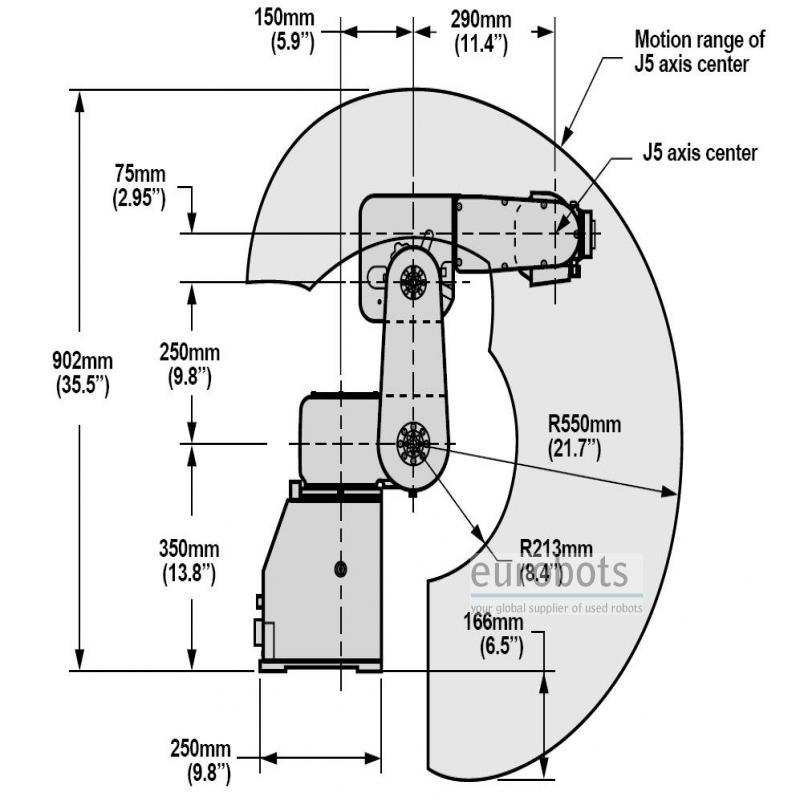

#### 6. Tabla de parámetros DH.

# FALTA

#### 7. Qué software utiliza el fabricante para diseño de celdas o programación.

el Fabricante Fanuc, emplea su propio software llamado  ROBOTSE SOFTWARE y para este robot el controlador  estándar de Fanuc  R-30iB Plus  es el que mejor se adapta a las necesidades de control de este modelo en especifico.

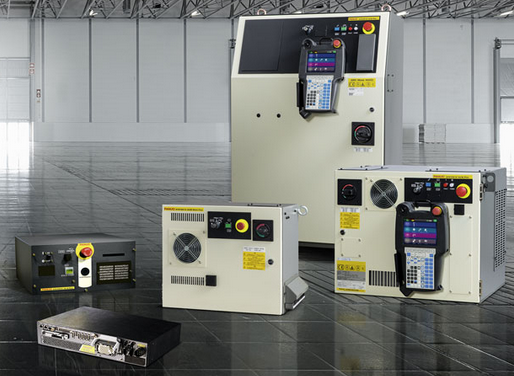

por otra parte se el mando a distancia en esta familia de robots se conoce como i-pendant y se muestra a continuacion:

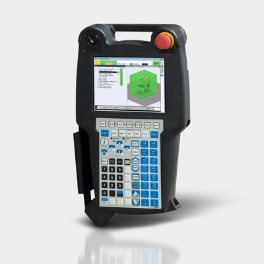

### Modelos

#### Peter Corke


%% Robot RPRRR 5 gdl
clf
clc
L1 = 2;L2 = 1; L3 = 1;L4 = 0.707*1;L5 =0.707*1; 
L4a = 0.707*1;
% ws =   [-10 10 -10   10 -10 10];
ws = [-70 80 -70 80 -20 70]/10;

 plot_options = {'workspace',ws,'scale',.5,'view',[125 25], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };

%            Theta  d   a   alpha  type mdh offset  qlim
L(1) = Link('revolute'   ,'alpha',      0,  'a',  0,     'd',    L1 , 'offset',     0, 'qlim',  [-2*pi/3 2*pi/3],   'modified');
L(2) = Link('prismatic'  ,'alpha',  -pi/2,  'a',  0, 'theta',     0 , 'offset',    L2, 'qlim',       [0     7*1],   'modified');
L(3) = Link('revolute'   ,'alpha',  -pi/2,  'a',  0,     'd',     L3, 'offset', -pi/2, 'qlim',  [-2*pi/3 2*pi/3],      'modified');
L(3) = Link('revolute'   ,'alpha',  -pi/2,  'a',  0,     'd',     L3, 'offset', -pi/2, 'qlim',  [-2*pi/3 2*pi/3],      'modified');
L(4) = Link('revolute'   ,'alpha',  -pi/2,  'a',  0,     'd',     0 , 'offset',     0, 'qlim',  [-2*pi/3 2*pi/3], 'modified');
L(5) = Link('revolute'   ,'alpha',  -pi/2,  'a',  L4a,   'd',     L4, 'offset',     0, 'qlim',  [-2*pi/3 2*pi/3], 'modified');
L(6) = Link('revolute'   ,'alpha',  -pi/2,  'a',  L4a,   'd',     L4, 'offset',     0, 'qlim',  [-2*pi/3 2*pi/3], 'modified');
Robot_Fanuc = SerialLink(L,'name','Robot_RPRRR','plotopt',plot_options)

 
Robot_Fanuc = 
 
Robot_RPRRR (6 axis, RPRRRR, modDH, fastRNE)                     
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          2|          0|          0|          0|
|  2|          0|         q2|          0|     -1.571|          1|
|  3|         q3|          1|          0|     -1.571|     -1.571|
|  4|         q4|          0|          0|     -1.571|          0|
|  5|         q5|      0.707|      0.707|     -1.571|          0|
|  6|         q6|      0.707|      0.707|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0      

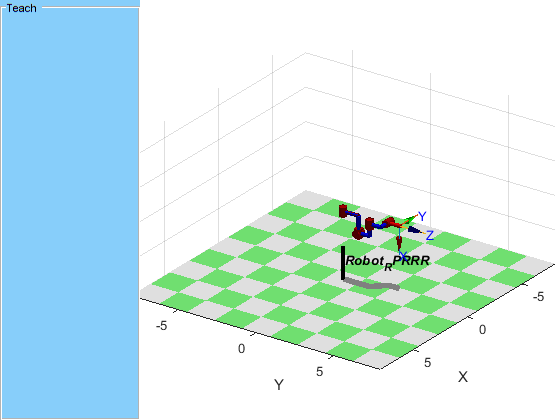

Error using SerialLink/plot (line 200)
Insufficient columns in q

Error in SerialLink/teach (line 168)
    robot.plot(q);



%%
Robot_Fanuc.tool = [ 0  0   1  L5;...
               1  0   0  0 ;...
               0  1   0  0 ;...
               0  0   0  1  ];

%%
q = [0 0 0 0 0];

Robot_Fanuc.teach(q)


%%
hold on
trplot(eye(4),'length',2 )

%% Solucion problena geometrico directo
TCP = Robot_Fanuc.fkine(q)
trplot(TCP,'length',2 )
tr2rpy(TCP,'zyx','deg')

# Pruebitas

testRobot = loadrobot('fanucLRMate200ib', 'DataFormat', 'row', 'Gravity', [0 0 -9.81])
testRobot1 = loadrobot('kinovaGen3', 'DataFormat', 'row', 'Gravity', [0 0 -9.81])
show(testRobot)
trvec2tform([0.4 0 0.6])

# #################################################################

My code starts here!

### Robotics Systems Toolbox (RST) de MATLAB®

Se comienza cargando el robot FANUC LR Mate 200*i*B con la ayuda de la función *loadrobot()* del *RST*, esto crea un objeto tipo *rigidBodyTree* con las características geométricas del manipulador.

FANUCLRMate200iB = loadrobot('fanucLRMate200ib', 'DataFormat', 'row', 'Gravity', [0 0 -9.81])

FANUCLRMate200iB =   rigidBodyTree with properties:

     NumBodies: 9
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'link_1'  'link_2'  'link_3'  'link_4'  'link_5'  'link_6'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 -9.8100]
    DataFormat: 'row'


Se establece la posición de *home* por defecto del robot como la configuración actual.

currentJointConfig = homeConfiguration(FANUCLRMate200iB);

Se obtiene el número de articulaciones y se rescata el nombre del elemento que representa al efector final.

numJoints = numel(currentJointConfig);
endEffector = 'tool0';

Se especifica el tiempo de paso de la trayectoria y la velocidad aproximada deseada de la herramienta.

timeStep = 0.2; % s
toolSpeed = 0.5; % m/s

Se configuran las poses iniciales y finales del efector final.

jointInit = currentJointConfig;
taskInit = getTransform(FANUCLRMate200iB, jointInit, endEffector)

taskInit =     0.0000    0.0000    1.0000    0.5200
         0   -1.0000    0.0000         0
    1.0000   -0.0000   -0.0000    0.6750
         0         0         0    1.0000


taskFinal = trvec2tform([0.7 0 0.4])*axang2tform([0 1 0 pi])

taskFinal =    -1.0000         0    0.0000    0.7000
         0    1.0000         0         0
   -0.0000         0   -1.0000    0.4000
         0         0         0    1.0000


## Generaración de la Trayectoria en el Espacio de Trabajo

Se computa primero la distancia que recorrerá la herramienta en la trayectoria.

firstDistance = norm(tform2trvec(taskFinal) - tform2trvec(taskInit))

firstDistance = 0.3287

Luego, se definen los tiempos de la trayectoria basados en la distancia y en la velocidad de la herramienta deseada.

initTime = 0;
finalTime = (firstDistance/toolSpeed) - initTime;
trajTimes = initTime: timeStep: finalTime;
timeInterval = [trajTimes(1) trajTimes(end)]

timeInterval =          0    0.6000


Se interpola entre las tramas inicial y final de la herramienta para computar los puntos vía (*waypoints*) intermedios en el espacio de trabajo.

[taskWaypoints, taskVelocities] = transformtraj(taskInit, taskFinal, timeInterval, trajTimes)

taskWaypoints = taskWaypoints(:,:,1) =

    0.0000    0.0000    1.0000    0.5200
    0.0000   -1.0000    0.0000         0
    1.0000   -0.0000   -0.0000    0.6750
         0         0         0    1.0000


taskWaypoints(:,:,2) =

   -0.2500    0.6124    0.7500    0.5800
    0.6124   -0.5000    0.6124         0
    0.7500    0.6124   -0.2500    0.5833
         0         0         0    1.0000


taskWaypoints(:,:,3) =

   -0.7500    0.6124    0.2500    0.6400
    0.6124    0.5000    0.6124         0
    0.2500    0.6124   -0.7500    0.4917
         0         0         0    1.0000


taskWaypoints(:,:,4) =

   -1.0000         0    0.0000    0.7000
         0    1.0000         0         0
   -0.0000         0   -1.0000    0.4000
         0         0         0    1.0000


taskVelocities =    -3.7024   -3.7024   -3.7024   -3.7024
   -0.0000   -0.0000   -0.0000   -0.0000
    3.7024    3.7024    3.7024    3.7024
    0.3000    0.3000    0.3000    0.3000
         0         0         0         0
   -0.4583   -0.4583   -0.4583   -0.4583


rotations = tform2quat(taskWaypoints)

rotations =     0.0000   -0.7071   -0.0000   -0.7071
    0.0000   -0.6124   -0.5000   -0.6124
    0.0000   -0.3536   -0.8660   -0.3536
    0.0000         0    1.0000         0


translations = tform2trvec(taskWaypoints)

translations =     0.5200         0    0.6750
    0.5800         0    0.5833
    0.6400         0    0.4917
    0.7000         0    0.4000


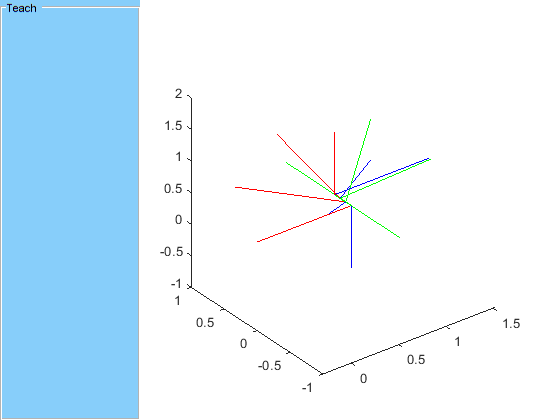

plotTransforms(translations, rotations)

## Control de Movimiento en el Espacio de Trabajo

Se crea un modelo en el espacio de las articulaciones para un control PD en las articulaciones. 

tsMotionModel = taskSpaceMotionModel('RigidBodyTree', FANUCLRMate200iB, 'EndEffectorName', endEffector)

tsMotionModel =   taskSpaceMotionModel with properties:

      RigidBodyTree: [1×1 rigidBodyTree]
    EndEffectorName: 'tool0'
       JointDamping: [1 1 1 1 1 1]
         MotionType: 'PDControl'
                 Kp: [6×6 double]
                 Kd: [6×6 double]


Se establecen las ganancias proporcional y derivativa sobre la orientación en cero, de manera que este comportamiento contralado solo siga la referencia de la posición.

tsMotionModel.Kp(1: 3, 1: 3) = 0;
tsMotionModel.Kd(1: 3, 1: 3) = 0;

Se definen los estados iniciales (posiciones y velocidades de las articulaciones).

q0 = currentJointConfig;
qd0 = zeros(size(q0));

Se utiliza un solucionador de ecuaciones diferenciales ordinarias (ODE) que mejor se acomode al problema del control de movimiento del manipulador. Debido a la simplicidad de este procedimiento en cuanto a la complejidad de la ODE, se hace uso de la función *ode45()*.

[timeTask, stateTask] = ode15s(@(t, state) derivative(tsMotionModel, state, taskInit, zeros(6, 1)), timeInterval, [q0 qd0])

Error using derivative
Expected state to be non-NaN.

Error in taskSpaceMotionModel/derivative (line 216)
            validateattributes(state, {'double'}, {'nonempty', 'vector', 'numel', 2*obj.NumJoints, 'nonnan', 'real'}, 'derivative', 'state');

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('FinalLaboratory', 'C:\Users\jorge\Desktop\JORGE LUIS\Universidad Nacional de Colombia\13th Semester\Robotics\Laboratories\Final Laboratory\Laboratorio-2-2021-1\FinalLaboratory.mlx', 69)" style="font-wei

## Generar la Trayectoria en el Espacio de las Articulaciones

Se crea la cinemática inversa del objeto para el robot.

invKin = inverseKinematics('RigidBodyTree', FANUCLRMate200iB)
invKin.SolverParameters.AllowRandomRestart = false;
linkWeights = [1 1 1 1 1 1];

Se calcula la configuración inicial y final deseada para las articulaciones usando la cinemática inversa. Se hace una restricción para que la interpolación se encuentre sobre el dominio mínimo.

initialGuess = jointInit
jointFinal = invKin(endEffector, taskFinal, linkWeights, initialGuess)

wrappedJointFinal = wrapToPi(jointFinal)

Se interpola usando una función polinomial cúbica para generar un arreglo de configuraciones de articulaciones equidistantes.

ctrlPoints = [jointInit' wrappedJointFinal']
jointConfigArray = cubicpolytraj(ctrlPoints, timeInterval, trajTimes)
jointWayPoints = bsplinepolytraj(jointConfigArray, timeInterval, 1)

Control de la Trayectoria en el Espacio de las Articulaciones

Se crea un modelo de control PD sobre el modelo de movimiento de las articulaciones. 

jsMotionModel = jointSpaceMotionModel('RigidBodyTree', FANUCLRMate200iB, 'MotionType', 'PDControl')

Se configura el estado inicial (velocidades y posiciones de las articulaciones)

q0 = currentJointConfig
qd0 = zeros(size(q0))

My Code ends here!

# #################################################################

Se debe construir primero el manipulador que ha sido asignado usando las estrategias del tutorial *Build a Robot Step by Step* de la documentación de MathWorks. Para esto, se toman los datos de la tabla de especificaciones del fabricante del robot.

Creación de eslabones del robot.

esl1 = rigidBody('Eslabón1')
esl2 = rigidBody('Eslabón2')
esl3 = rigidBody('Eslabón3')
esl4 = rigidBody('Eslabón4')
esl5 = rigidBody('Eslabón5')
esl6 = rigidBody('Eslabón6')

 Creación de las articulaciones del robot

art1 = rigidBodyJoint('Articulación1', 'revolute')
art2 = rigidBodyJoint('Articulación2', 'revolute')
art3 = rigidBodyJoint('Articulación3', 'revolute')
art4 = rigidBodyJoint('Articulación4', 'revolute')
art5 = rigidBodyJoint('Articulación5', 'revolute')
art6 = rigidBodyJoint('Articulación6', 'revolute')

Establecimiento de las posiciones de *home* para las articulaciones.

art1.HomePosition = 0
art2.HomePosition = 0
art3.HomePosition = 0
art4.HomePosition = 0
art5.HomePosition = 0
art6.HomePosition = 0

Creación de las matrices de transformación homogéneas para las articulaciones.

tform1 = trvec2tform([0 0 0])

ActualRobotJConfig = homeConfiguration(RobotFANUC); %definicion del Home segun el RObot Importado
numJoints = numel(ActualRobotJConfig); %numero de Juntas
endEffector = "EndEffector_Link";      %
show(RobotFANUC);
timeStep = 0.1;                        % tiempo de desplazamiento en segundos
toolSpeed = 0.1;                       % Velocidad de la herramienta en m/s 
jointInit = ActualRobotJConfig;        %configuracion inicial del efector final
taskInit = getTransform(RobotFANUC,jointInit,endEffector); %inicio de la tarea de movimiento

taskFinal = trvec2tform([0.4,0,0.6])*axang2tform([0 1 0 pi]); %coordenadas finales de la tarea

# Creación de la Trayectoria

alcanMax = 0.700 % m
long = 0.4*alcanMax
vel = 0.500 % m/s
tiempo = (0: 0.2: 10)' % s
cont = length(tiempo)
centro = [0.7 0 0.4]
radio = 0.095
% puntos = centro + 

PARTE 3

JACOBIANO